clc; clear all; close all;

img_path = fullfile('OD_zoom_sinCaps_1205_SQ_9_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('metadata', 'Correct.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);


%for u = 1:height(T)
    k=2

k = 2

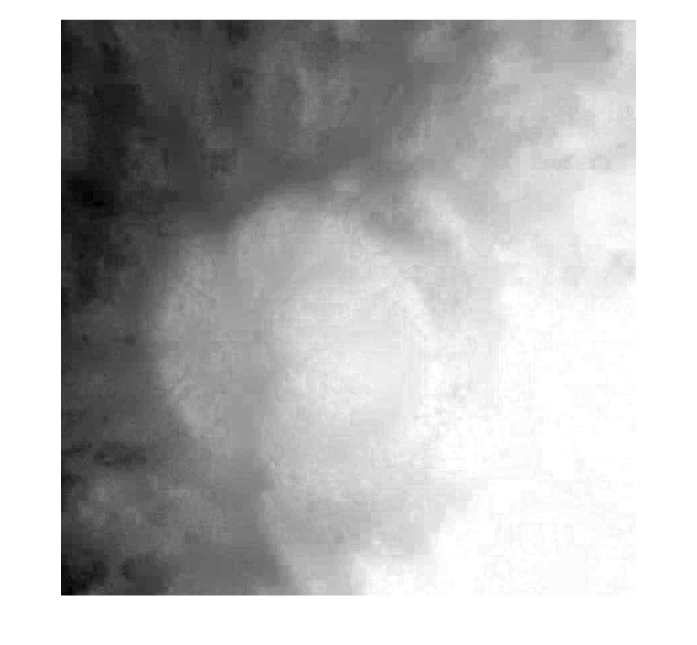

    RGB = imread(string(fullfile(img_path, T{k,1})));
    R=RGB(:,:,1);
    LAB=rgb2lab(RGB);
    L=LAB(:,:,1);

    figure;
    imshow(R,[]);

L=histeq(L);
figure;
imshow(L,[]);

    binL=de2bi(L);
figure;
    for i=1:7
subplot(1, 7, i);
imshow(binL(:,i));
    end